# Laboratório de Controle - Aula 1 - 2021/1

## Introdução às simulações no Matlab e Simulink

## **Nome**: Yuri Rissi Negri

**Atividade 1:** **Simulação de uma função de transferência de primeira ordem**

Na figura 1 é mostrada a resposta ao degrau de um sistema de primeira ordem, destacando a constante de tempo e o tempo de estabelecimento.

Se tiver dúvidas, veja [Constante de tempo](https://pt.wikipedia.org/wiki/Constante_de_tempo)

Atribua a I o valor que recebeu, e execute a próxima seção de código, observando o resultado da simulação à direita.

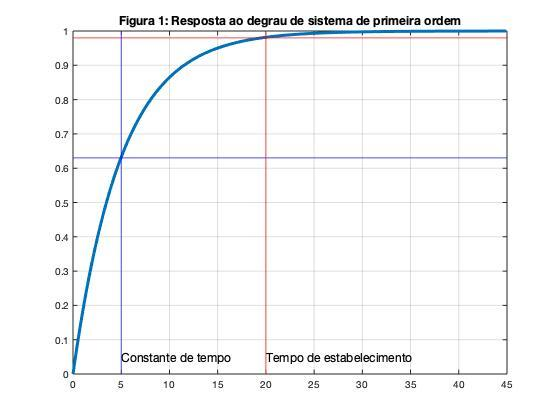

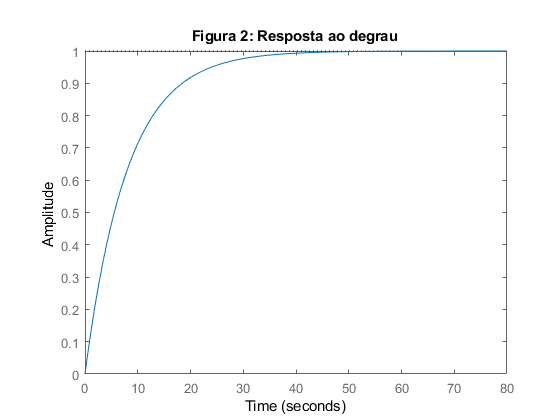

I=8; 
wn=I; 
g=tf(1,[I 1]);
figure(2);step(g);title('Figura 2: Resposta ao degrau');

1.1 Observe a Figura 1 e explique como obter a constante de tempo de um sistema de primeira ordem.

Resposta: 

Por definição, a constante de tempo será o tempo necessário para que o sistema atinja 63,2% do valor que ele atinge quando o mesmo se estabiliza. Assim, graficamente podemos encontrar a constante de tempo encontrando o ponto no grafico onde essa condição é satisfeita, como é representado na Figura 1.

1.2 Observe a Figura 2 e obtenha sua constante de tempo (aproximada)

Resposta:

Tomando o ponto aproximado onde nosso valor é de Y= 0,637, vamos obter para I=8 uma constante de tempo de aproximadamente 8,1 segundos.

1.3 Observe a Figura 1 e explique como obter o tempo de estabelecimento de um sistema de primeira ordem. Tendo dúvidas, veja [Tempo de estabelecimento](https://en.wikipedia.org/wiki/Settling_time)

Resposta:

É o tempo necessário para que o nosso sistema antija e mantenha uma faixa de valores iguais ou menores que 2% (ou 5%) em torno do valor final para o qual nosso sistema ira se aproximar. Podemos confirmar a teoria observando novamente o gráfico representado na Figura 1.

1.4 Observe a Figura 2 e obtenha o tempo de estabelecimento  (aproximado)

Resposta:

Analogamente ao item 1.2, como nosso sistema se aproxima do valor final Y= 1, tomando graficamente o ponto Y = 0,98  obtemos para o nosso sistema um tempo de estabelecimento de aproximadamente 31,3 segundos.

**Atividade 2:** **Efeito do ganho na resposta em malha fechada**

Seja a FT $G(s)=\frac{k}{\tau s+1}$. Em malha fechada tem-se $M(s)=\frac{k}{\tau s + 1 + k}$

O slider abaixo muda o ganho k, alterando o único polo de $M(s)$. Para cada alteração, uma nova simulação é feita com o valor escolhido. Experimente.


k=0.01

k = 0.0100

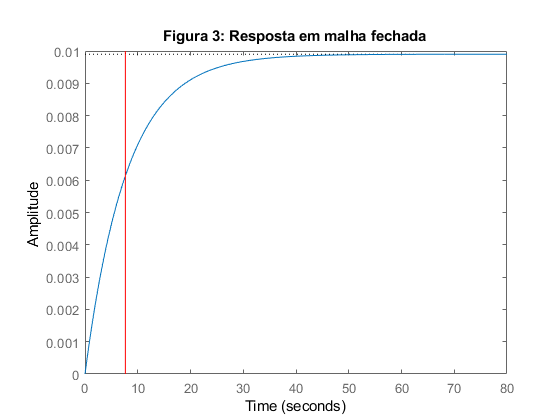

;
m=feedback(k*g,1);
figure(3);step(m);title('Figura 3: Resposta em malha fechada');
[y,t]=step(m);
d=sum(y<0.63*y(end));
line(t(floor(d))*[1;1],[0;1],'Color','r');

2.1 Clique 2 vezes sobre o slider e escolha os valores mínimos e máximos, de forma que para o valor mínimo de k se tenha a constante de tempo igual a de malha aberta e para o máximo de k se tenha 10% do valor da constante de tempo em malha aberta.  Quais os valores máximo e mínimo que obteve de k?

Resposta:

Quanto menor o valor de K, mais nos aproximamos do valor da constante de tempo de malha aberta. Então para K mínimo, podemos adotar um valor de 0,01 que nos da numa boa aproximação. Para K máximo, temos que adotar um valor que nos resulte em uma constante de tempo de aproximadamente 0,8 segundos, assim tomando K máximo igual a 8,5 obtemos uma boa aproximação.  

2.2 Sabendo que o valor de regime de $M(s)$ pode ser obtido pelo teorema do valor final, $Y(s)=M(s)R(s)$, $lim_{s\to 0}s Y(s)= lim_{s\to 0}sM(s)\frac{1}{s}=M(0)$, e usando a figura 3, explique o efeito do ganho k no valor final da saída. Dúvidas, veja [Teorema do valor final](https://pt.wikipedia.org/wiki/Teorema_do_valor_final) . Dica: vejam o comando [freqresp](https://www.mathworks.com/help/control/ref/lti.freqresp.html) para obter $M(0)$.

Resposta:

Utilizando o teorema do valor final, obtemos a função k/(k+1). Dessa forma, fica fácil perceber a influência de k no valor final da saída do nosso sistema. Para valores de k muito grande, onde k >> 1, podemos aproximar nossa função de forma a termos k/k= 1, ou seja, para valores de k muito grandes, o valor final da nossa saída irá ser de aproximadamente 1. A mesma analise pode ser feita para valores muito pequenos de k, onde k<<1, assim podemos aproximar nossa função para k/1= k, ou seja, quanto menor for nosso k, mais o valor final da nossa saída irá se aproximar ao próprio k. Podemos comprovar isso ao analisar o gráfico alterando a faixa de valores de k.

**Atividade 3:** **Avaliação do efeito do ganho na constante de tempo usando múltiplas simulações **

O comando linspace é usado agora para gerar 10 valores de ganho k entre os valores mínimo e máximo que escolheu na atividade 2.1. O formato do comando é k=linspace(kmin,kmax,10). Abaixo a simulação para cada valor de ganho é repetida 10 vezes e uma figura com o ganho versus a constante de tempo é mostrada.

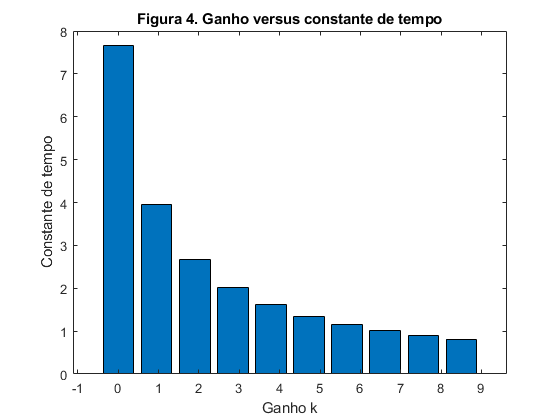

k=linspace(0.01,8.5,10); % Substitua kmin e kmax pelos obtidos
for i=1:10
    m=feedback(k(i)*g,1);
    [y,t]=step(m);
    ct(i)=t(floor(sum(y<0.63*y(end))));
end
figure(4);bar(k,ct);xlabel('Ganho k');ylabel('Constante de tempo');
title('Figura 4. Ganho versus constante de tempo');

 3.1 Explique a Figura 4, levando em consideração a análise que fez na atividade 2.1

Resposta:

Pelo gráfico e pelos valores obtidos na atividade 2, podemos perceber que a medida que diminuímos o valor de k, nos aproximamos da nossa constante de tempo em malha aberta , e que conforme aumentamos o valor de k, obtemos um valor cada vez menor para nossa constante de tempo.

**Atividade 4: Simulação do arquivo slx do Simulink**

O comando **sim** é utilizado para simular diagramas do Simulink no ambiente do Matlab. O formato é sim(arquivo,tempo), sendo arquivo uma string e tempo uma constante que define o tempo total de simulação. Exemplo: sim('aula1_R2018.slx',10); Help do [comando sim](https://www.mathworks.com/help/simulink/slref/sim.html).

A figura 5 mostra o diagrama simulado. É aplicado um degrau R, e obtem-se a saída Y. Tanto o sinal de entrada quanto de saída são mostrados no bloco scope de saída, e são gravados em uma variável X, que é plotada no ambiente do Matlab, e é uma matriz da forma X=[ tempo Entrada Saída]. A sintaxe dos comandos para simular e obter X depende da versão do Matlab, conforme abaixo:

**Matlab 2018 em diante**

out=sim(arquivo,Tempo);

Y=out.X(:,[2,3]);

t=out.tout;

**Matlab anterior a 2018**

sim(arquivo,Tempo);

Y=X(:,[2,3]);

t=X(:,1);

O parâmetro que afeta a simulação é wn, que é definido no ambiente do Matlab antes de cada simulação.

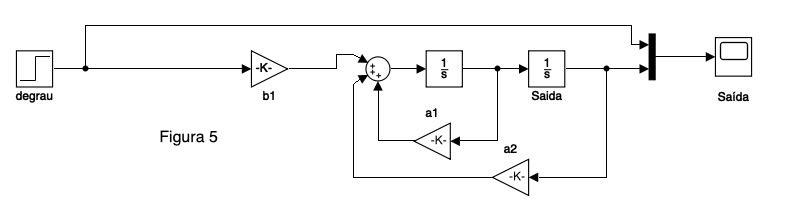

**Atividade 4.1: **Simular o diagrama usando os comandos adequados e com o tempo adequado, e plotar a resposta e a entrada aplicada. Informe o tempo de estabelecimento e constante de tempo desse sistema.

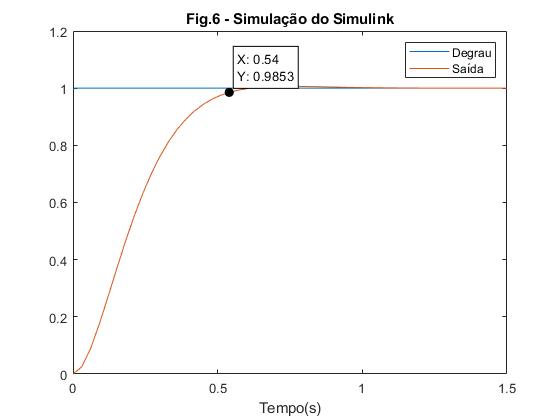

Tempo=1.5; 
out=sim("aula1_R2018.slx",Tempo);
Y=out.X(:,[2,3]);
t=out.tout;
plot(t,Y);legend('Degrau','Saída');xlabel('Tempo(s)');title('Fig.6 - Simulação do Simulink');

Do gráfico, tomando o ponto Y= 0,6285 obtemos um valor de X de 0,24 segundos, o que nos da uma boa aproximação da nossa constante de tempo. Já para o tempo de estabelecimento, tomando o ponto Y= 0,9853, obtemos um valor aproximado de 0,54 segundos.   

Ou o código abaixo (comentar o que não usar):

%Tempo=1; % Escolher valor
%sim("aula1_R2015.slx",Tempo);
%Y=X(:,[2,3]);
%t=X(:,1);
%plot(t,Y);legend('Degrau','Saída');xlabel('Tempo(s)');title('Fig.7 - Simulação do Simulink');

datetime('now')

ans = datetime
   18-Jun-2021 11:25:26


pwd

ans = 'C:\Users\asus1\Desktop\Aula1'